Error in db0_2.jpg


Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds. Index must not exceed 1.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds. Index must not exceed 1.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Er

Error in cl_1.jpg


Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.


Error in cl_15.jpg


Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds. Index must not exceed 1.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds. Index must not exceed 1.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.


Error in il_1.jpg


Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.


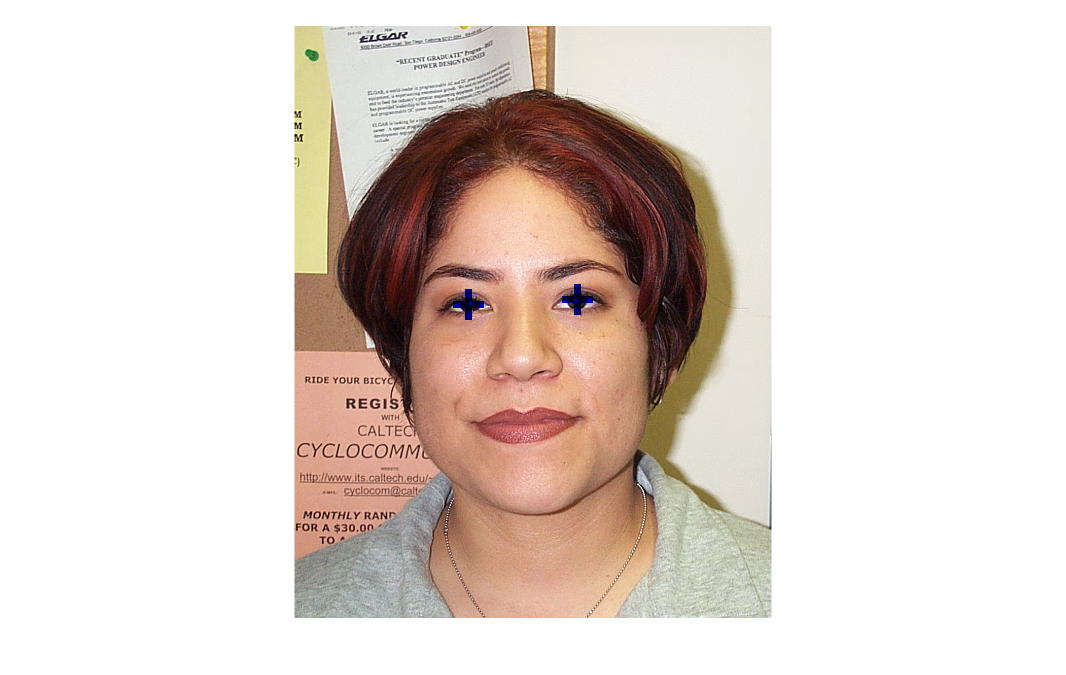

clear all

% Load face images from a folder
imageDir = 'Faces/';
imageDir2 = 'Faces/DB2/';
testimages = dir(fullfile(imageDir, '*.jpg'));
testimages2 = dir(fullfile(imageDir2, '*.jpg'));
allImages = [testimages; testimages2];
numImages = numel(allImages);

% Read images into a cell array
faceData = cell(1, numImages);
for i = 1:numImages
    % Load your image
    im = im2double(imread(fullfile(allImages(i).folder, allImages(i).name)));
    %mask = double(skinMask(im));  
    %imshow(im.*mask);title(allImages(i).name)
    try
        [eye1,eye2] = findEyes(im);

        imX = showEyes(im, eye1, eye2);
        imshow(imX);title(allImages(i).name)
    catch
        disp("Error in " + allImages(i).name)
    end
    pause(0.1)
end

## TEsts

    % Load your image
    im = im2double(imread("Faces/db0_" + 4 + ".jpg"));
    mask = double(skinMask(im));  
    imshow(im.*mask);
    [eye1,eye2] = findEyes(im);
    
    imX = showEyes(im, eye1, eye2);
    imshow(imX);
    pause(0.1)

function test = testa(imIn)
%imIn = im2double(imread("Faces/db1_" + 3 + ".jpg"));
imIn = colorCorrection(imIn);
imIn = AWB(imIn,20);
imIn = adjustRGB(imIn);
%imIn = contrastStretchColor(imIn,0,1);
% Convert the RGB image to YCgCr color space
ycgcrImage = rgb2ycgcr(imIn);

% Extract the Y, Cb, and Cr channels
Y = ycgcrImage(:, :, 1);
Cg = ycgcrImage(:, :, 2);
Cr = ycgcrImage(:, :, 3);

% Define thresholds for skin color in YCbCr space
% Trail and Error Values
Ymin = 0.3;
Ymax = 0.92;
Cgmin = 0.3;
Cgmax = 0.55;
Crmin = 0.06;
Crmax = 0.17;

crmask = ~(Crmin <= Cr & Cr <= Crmax);
SE = strel('disk', 2);
crmask = imclose(crmask, SE);
SE = strel('disk', 12);
crmask = imerode(crmask, SE);
SE = strel('rectangle', [80 5]);
crmask = imclose(crmask, SE);
SE = strel('rectangle', [80 5]);
crmask = imopen(crmask, SE);
SE = strel('rectangle', [5 10]);
crmask = imopen(crmask, SE);
crmask = imfill(crmask, 'holes');

%SE = strel('disk', 40);
%crmask = imopen(crmask, SE);
%imshow(crmask); title('crmask')

cgmask = ~(Cgmin <= Cg & Cg <= Cgmax);
%imshow(cgmask); title('cgmask')

ymask = (Ymin <= Y & Y <= Ymax);
SE = strel('disk', 6);
ymask = imclose(ymask, SE);
ymask = imfill(ymask, 'holes');
%imshow(ymask); title('ymask')

% Create binary masks for skin regions
mask = (ymask | cgmask) & crmask;

SE = strel('disk', 6);
mask = imerode(mask, SE);
mask = imclose(mask, SE);

SE = strel('disk', 19);% was 8 before 2023-11-22
mask = imdilate(mask, SE);
mask = imclose(mask, SE);

SE = strel('disk', 10);
mask = imclose(mask, SE);

% Filter image, retaining only the 5 objects with the largest areas.
mask = bwareafilt(mask,1);
SE = strel('disk', 350);
mask = imclose(mask, SE);
mask = imfill(mask, 'holes');

test = mask.*imIn;
%imshow(mask.*imIn); title('mask')
end

function [mask] = faceMask(rgbImage)
    HSV = rgb2hsv(rgbImage);
    H = HSV(:,:,1);
    YCBCR = rgb2ycbcr(rgbImage);
    Cb = YCBCR(:,:,2);

    for i = 1:length(rgbImage(:,1,1))
        for j = 1:length(rgbImage(1,:,1))
           R = rgbImage(i,j,1);
           G = rgbImage(i,j,2);
           B = rgbImage(i,j,3);
           
           if ( H(i,j) < 0.85 && H(i,j) > 0.09)
               rgbImage(i,j,1) = 0;
               rgbImage(i,j,2) = 0;
               rgbImage(i,j,3) = 0;
           end
       
           if ( Cb(i,j) > 130 && Cb(i,j) < 100)
               rgbImage(i,j,1) = 0;
               rgbImage(i,j,2) = 0;
               rgbImage(i,j,3) = 0;
           end

        end
    end

    rgbImage = imbinarize(im2double(rgbImage(:,:,1)));
    
    % Clean the image
    rgbImage = imerode(rgbImage,strel('disk',2));
    rgbImage = imerode(rgbImage,strel('disk',1));
    rgbImage = imdilate(rgbImage,strel('disk',8));
    
    rgbImage = imfill(double(rgbImage));
    
    rgbImage = imdilate(rgbImage,strel('disk',8));
 
    rgbImage = imfill(double(rgbImage));
    
    rgbImage = imerode(rgbImage,strel('disk',10));
    
    mask = imerode(rgbImage,strel('disk',5));
end

function ycgcrImage = rgb2ycgcr(rgbImage)
    % Define the conversion matrix for RGB to YCgCr
    conversionMatrix = [0.299 0.587 0.114; -0.1687367 -0.331264 0.5; 0.5 -0.418688 -0.081312];
    
    % Convert the RGB image to YCgCr
    [rows, cols, ~] = size(rgbImage);
    ycgcrImage = zeros(rows, cols, 3);
    
    for i = 1:rows
        for j = 1:cols
            pixel = double(reshape(rgbImage(i, j, :), 3, 1));
            ycgcrPixel = conversionMatrix * pixel;
            ycgcrImage(i, j, :) = ycgcrPixel;
        end
    end

    % Normalize the YCgCr channels
    ycgcrImage(:, :, 2) = ycgcrImage(:, :, 2) + 0.5;
    ycgcrImage = min(max(ycgcrImage, 0), 1);
end
function adaptedImage = adjustRGB(imIn)
% Function for adjustment of color balance in RGB image using chromatic adaptation

% Turn image to double
imIn = im2double(imIn);

% Specify the illuminant color using illumwhite
illuminantColor = illumwhite(imIn, 1);

% Perform chromatic adaptation
adaptedImage = chromadapt(imIn, illuminantColor,'ColorSpace', 'prophoto-rgb');
end
